%PRE-PROCESSING
clear
file = "MC1\dataFile.mat";
load(file);

%Conversion to timetable type to utilize MATLAB functions specifically to
%this type.
data = table2timetable(mc1reportsdata);
data = sortrows(data);

% Table of only damage intensity data.
damages = mc1reportsdata(:, ["medical", "sewer_and_water", "power", ...
                "roads_and_bridges", "buildings", "shake_intensity"]);

%Damage types conversion to categorical for plotting purposes.
types = damages.Properties.VariableNames;
types = categorical(types);

%Number of areas in order for plotting.
numAreas = 1:19;

%Filtering data based on prequake, mainshock and aftershock.
prequake_index = timerange('2020-04-06 14:00:00', '2020-04-07 00:00:00');
mainshock_index = timerange('2020-04-08 07:00:00', '2020-04-09 00:00:00');
aftershock_index = timerange('2020-04-09 11:00:00', '2020-04-10 00:00:00');

earthquake_index = timerange('2020-04-06 14:00:00', '2020-04-10 00:00:00');

prequake_table = data(prequake_index,:);
mainshock_table = data(mainshock_index,:);
aftershock_table = data(aftershock_index,:);
earthquake_table = data(earthquake_index,:);

## OVERALL DAMAGE ACROSS ALL CATEGORIES AND AREAS

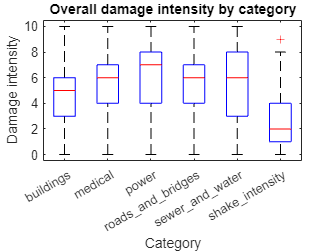

boxplot(damages{:,:}, types);
title('Overall damage intensity by category')
xlabel('Category')
ylabel('Damage intensity')

## NUMBER OF REPORTS TO APPROX. POPULATION SIZE FOR EACH NEIGHBORHOOD.

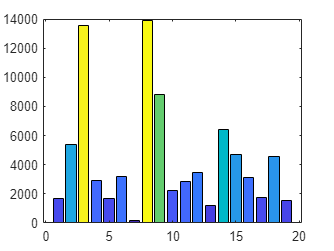

numReports = hist(data{:,"location"},numAreas);
out = [numAreas; numReports];

b = bar(numAreas, numReports, 'FaceColor', 'flat');

b.CData = numReports / max(numReports);

## TAKING A CLOSER LOOK AT THE SHAKE INTENSITY DURING FORESHOCK, MAINSHOCK AND AFTERSHOCK.

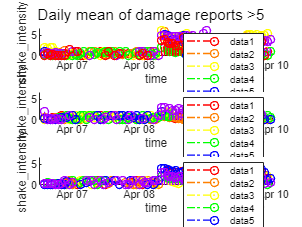

for i = 1:length(numAreas)
    earthquake_rows = earthquake_table{:,'location'} == numAreas(i);
    rolling_earthquake_mean{i} = retime(earthquake_table(earthquake_rows,"shake_intensity"), "hourly", "mean");
    
end

% REMOVE NAN TO SOLVE CONFLICTS WITH PLOT FUNCTIONS.
for j = 1 : length(numAreas)
    rolling_earthquake_mean{j} = rmmissing(rolling_earthquake_mean{j});
end

order = [2 3 4 6 7 12 13];
order2 = [1 5 8 9 10 11];
order3 = [14 15 16 17 18 19];
plotColors = jet(19);
cmap = colormap(prism(7));

subplot(3,1,1);
hold on
for k = 1:length(order)

    stem(rolling_earthquake_mean{order(:,k)}, "shake_intensity",'Color', cmap(k,:), 'Marker','o','LineStyle','-.' , 'LineWidth', 1);
end
hold off
legend show
ylim([0 6.7])

subplot(3,1,2);
hold on
for ik = 1:length(order2)
    stem(rolling_earthquake_mean{order2(:,ik)}, "shake_intensity", 'Color', cmap(ik,:), 'Marker','o', 'LineStyle','-.', 'LineWidth',1);
end
hold off
legend show
ylim([0 6.7])

subplot(3,1,3);
hold on
for jk = 1:length(order3)

    stem(rolling_earthquake_mean{order3(:,jk)}, "shake_intensity", 'Color', cmap(jk,:), 'Marker','o', 'LineStyle','-.','LineWidth',1);
end
hold off 
legend show
ylim([0 6.7])

## TAKING A CLOSER LOOK AT BUILDING, POWER ETC DAMAGES DURING PRESHOCK, MAINSHOCK AND AFTERSHOCK FOR THE MOST DAMAGED AREAS.

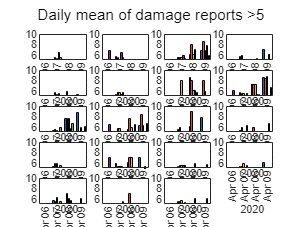

mostDamaged = [3, 4, 7, 12];

for i = 1:length(numAreas)
    earthquake_rows = earthquake_table{:,'location'} == numAreas(i);
    rolling_earthquake_mean{i} = retime(earthquake_table(earthquake_rows,1:5), "daily", "mean");
end
for j = 1 : length(numAreas)
    %rolling_earthquake_mean{j} = rmmissing(rolling_earthquake_mean{j});
end

figure(1)
for k = 1:19
    subplot(5,4, k);

    %s(:,k) = bubblechart(rolling_earthquake_mean{:,k}, 1:5,'time', 5);
    %sc = scatter(rolling_earthquake_mean{:,k}, 'time', [1:5])
    b(:,k) = bar(rolling_earthquake_mean{:,k}.time, rolling_earthquake_mean{:,k}{:,1:5});
    ylim([5 10])

end

sgtitle('Daily mean of damage reports >5')

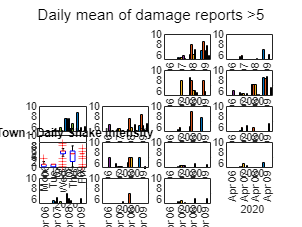

oldTown = data.location == 3;
SafeTown = data.location == 4;
WilsonForest = data.location == 7;
ScenicVista = data.location == 8;

oldTown = data(oldTown, :);
SafeTown = data(SafeTown, :);
WilsonForest = data(WilsonForest, :);
ScenicVista = data(ScenicVista, :);


[~, dayCol] = weekday(oldTown.time);
[~, dayCol2] = weekday(SafeTown.time);
[~, dayCol3] = weekday(WilsonForest.time);
[~, dayCol4] = weekday(ScenicVista.time);

subplot(2,2,1)
boxplot(oldTown.shake_intensity,dayCol);
title("Old Town - Daily Shake Intensity")

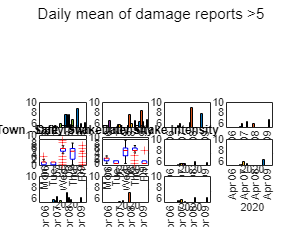

subplot(2,2,2);
boxplot(SafeTown.shake_intensity,dayCol2);
title("Safe Town - Daily Shake Intensity")

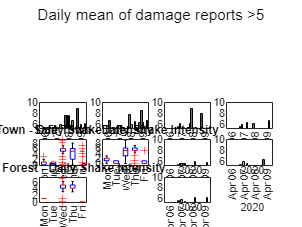

subplot(2,2,3);
boxplot(WilsonForest.shake_intensity,dayCol3);
title("Wilson Forest - Daily Shake Intensity")

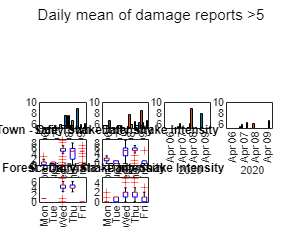

subplot(2,2,4);
boxplot(ScenicVista.shake_intensity,dayCol4);
title("Scenic Vista - Daily Shake Intensity")